CUSTOM TRANSFORMATION

1) Sacling

forward_fcn = @(wz, tdata)[3*wz(:, 1), 2*wz(:, 2)];
inverse_fcn = @(wz, tdata)[wz(:, 1)/3, wz(:, 2)/2];
tform1 = maketform("custom", 2, 2, forward_fcn, inverse_fcn, []);

WZ = [1 1;
      3 2];
XY = tformfwd(WZ, tform1)

XY =      3     2
     9     4


WZ2 = tforminv(XY, tform1)

WZ2 =      1     1
     3     2


2) Horizontal Shear

forward_fcn2 = @(wz, tdata)[wz(:, 1) + 0.4*wz(:, 2), wz(:, 2)];
inverse_fcn2 = @(wz, tdata)[wz(:, 1) - 0.4*wz(:, 2), wz(:, 2)];
tform2 = maketform("custom", 2, 2, forward_fcn2, inverse_fcn2, []);
tformfwd(WZ, tform2)

ans =     1.4000    1.0000
    3.8000    2.0000


3) Vertical Shear

forward_fcn3 = @(wz, tdata)[wz(:, 1), wz(:, 2) + 0.4*wz(:, 1)];
inverse_fcn3 = @(wz, tdata)[wz(:, 1), wz(:, 2)- + 0.4*wz(:, 1)];
tform3 = maketform("custom", 2, 2, forward_fcn3, inverse_fcn3, []);
tformfwd(WZ, tform3)

ans =     1.0000    1.4000
    3.0000    3.2000


 AFFINE TRANSFORMATION

T = [1 0.4 0;
    0.4 1 0;
    0 0 1];
tform4 = maketform("affine", T);
tformfwd(WZ, tform4)

ans =     1.4000    1.4000
    3.8000    3.2000


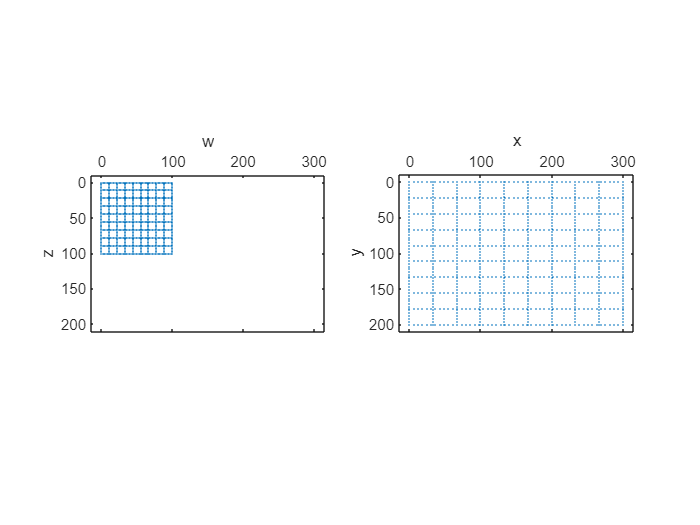

vistform(tform1, pointgrid([0 0; 100 100]));

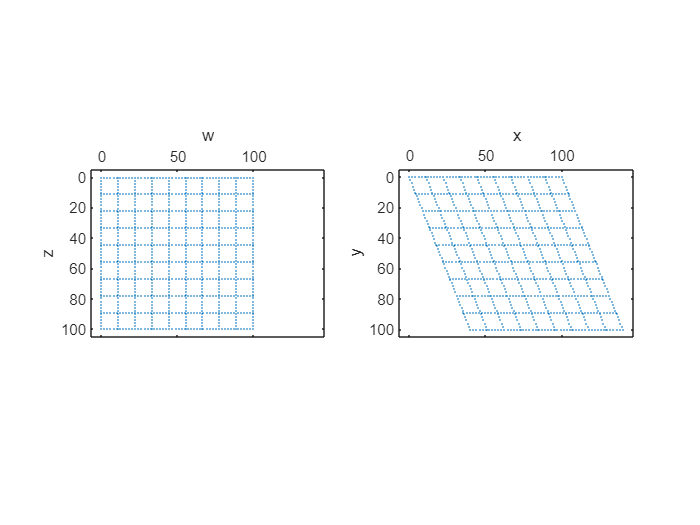

figure, vistform(tform2, pointgrid([0 0; 100 100]));

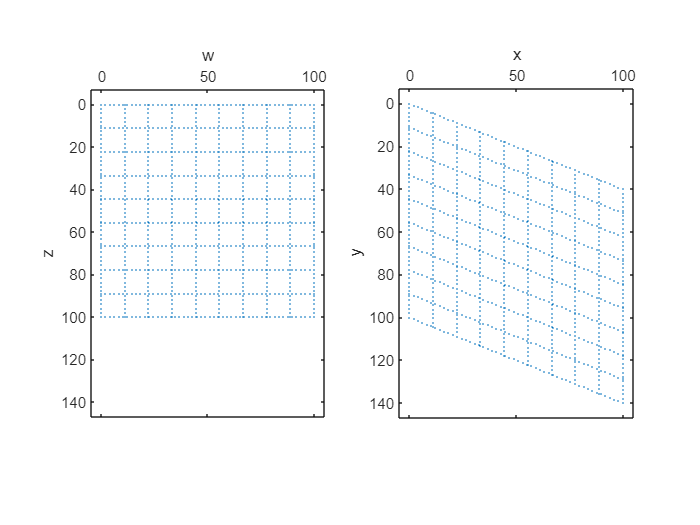

figure, vistform(tform3, pointgrid([0 0; 100 100]));

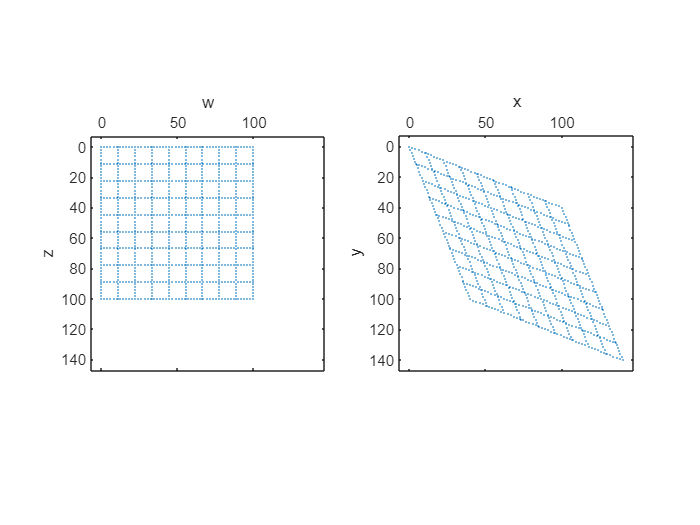

figure, vistform(tform4, pointgrid([0 0; 100 100]))

tform5 = maketform("affine", [1 1 0; 1 1 0; 0 0 1]);

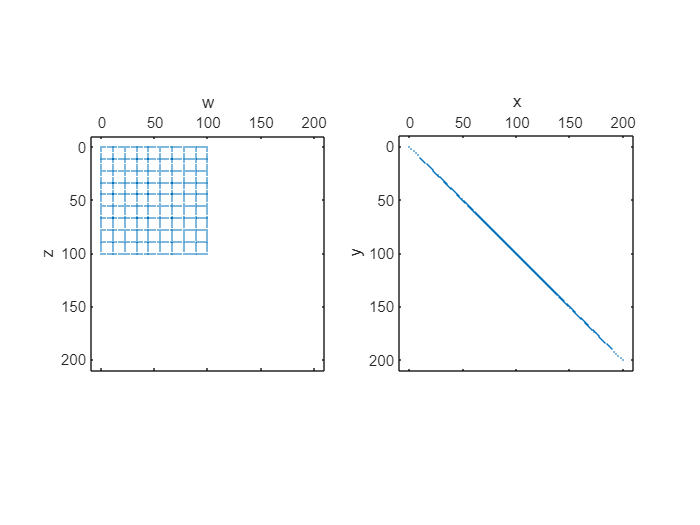

figure, vistform(tform5, pointgrid([0 0; 100 100]))